clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_colon_9_26.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

arm = 'psm3_fena';


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
    

      joint_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/joints/'];
      jacobian_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/jacobian/'];
      torque_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
%       joint_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/joints/'];
%       jacobian_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/jacobian/'];
%       torque_path = ['dvrk-si-3-15/csv_si/', test_folder, '/', data, '/', 'lstm', network];

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian.csv']);
torque_data = readmatrix(torque_path);

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =     0.0000   -0.0000    0.2057   -0.0000    0.0192   -0.0772
   -0.0000   -0.0000    0.5553    0.0000    0.0708    0.0236
    0.0000    0.0000   -0.8058   -0.0000    0.0537   -0.0035
    0.0000   -0.9689         0    0.2057   -0.9556   -0.2938
   -1.0000   -0.0000         0    0.5553    0.2916   -0.9541
    0.0000   -0.2474         0   -0.8058   -0.0430    0.0584



fs_pred_torque = torque_data(:,2:7).';
% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(fs_pred_torque),14:19).';
jacobian = jacobian(:,:,1:length(fs_pred_torque));

fs_diff = measured_torque - fs_pred_torque;
fs_force = zeros(6,length(fs_pred_torque));

%%%%% si
force_sensor_cal = [-0.88379, -0.37356, -0.2714676; -0.15279, 0.929125, 0.32620139; 0.098968, -0.33537, -0.9366509]

force_sensor_cal =    -0.8838   -0.3736   -0.2715
   -0.1528    0.9291    0.3262
    0.0990   -0.3354   -0.9367


%%%% classic
force_sensor_cal = [0.971011, 0.158129, -0.177306; 0.091309, -0.97246, 0.10079652; -0.04083, -0.13805, -0.9768911] 

force_sensor_cal =     0.9710    0.1581   -0.1773
    0.0913   -0.9725    0.1008
   -0.0408   -0.1381   -0.9769




force_sensor_cal = force_sensor_cal.'

force_sensor_cal =     0.9710    0.0913   -0.0408
    0.1581   -0.9725   -0.1381
   -0.1773    0.1008   -0.9769


[U, S, V] = svd(force_sensor_cal);
force_sensor_cal = U * V.'

force_sensor_cal =     0.9854    0.1375   -0.1006
    0.1241   -0.9838   -0.1297
   -0.1168    0.1153   -0.9864


force_sensor_cal = V * U.'

force_sensor_cal =     0.9854    0.1241   -0.1168
    0.1375   -0.9838    0.1153
   -0.1006   -0.1297   -0.9864



angle = pi/2;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]

Ra =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071]

Rz =    -1.0000         0         0
         0   -0.7071   -0.7071
         0   -0.7071    0.7071


% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz)

ans = 1.0000

another_angle = pi-1/4*pi;
rotation = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1]

rotation =    -0.7071   -0.7071         0
    0.7071   -0.7071         0
         0         0    1.0000



for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(jacobian(:,:,i).') * (fs_diff(:,i));
    fs_force(1:3, i) = rotation * fs_force(1:3, i);
end

fs_force = fs_force.';


real_force_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', 'test/', arm, '/', 'sensor/'];
% real_force_path = ['dvrk-si-3-15/csv_si/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);






windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force_unfilt = fs_force;

% fs_force = filter(b,a,fs_force);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));
loss_taux = mean(sqrt(mean( (fs_force(:,4) - real_force(:,4)).^2 )));
loss_tauy = mean(sqrt(mean( (fs_force(:,5) - real_force(:,5)).^2 )));
loss_tauz = mean(sqrt(mean( (fs_force(:,6) - real_force(:,6)).^2 )));

[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix)

boundX = 15.6278

[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy)

boundY = 7.5773

[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz)

boundZ = 21.1762

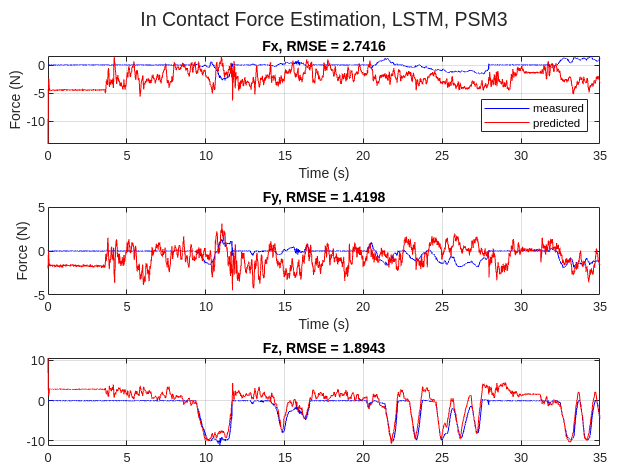


figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('In Contact Force Estimation, LSTM, PSM3'))

% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,1), 'b')
% hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
% plot(0.005 * (1:length(fs_force)), fs_force(:,1), 'r')
% xlabel('Time/s')
% ylabel('Force/N')
% hold off
% 
% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,2), 'b')
% hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
% plot(0.005 * (1:length(fs_force)), fs_force(:,2), 'r')
% xlabel('Time/s')
% ylabel('Force/N')
% hold off
% 
% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,3), 'b')
% hold on
% title(sprintf('Fz, RMSE = %.4f', loss_z))
% plot(0.005 * (1:length(fs_force)), fs_force(:,3), 'r')
% xlabel('Time/s')
% ylabel('Force/N')
% hold off
% 
% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,4), 'b')
% hold on
% title(sprintf('Taux, RMSE = %.4f', loss_taux))
% plot(0.005 * (1:length(fs_force)), fs_force(:,4), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,5), 'b')
% hold on
% title(sprintf('Tauy, RMSE = %.4f', loss_tauy))
% plot(0.005 * (1:length(fs_force)), fs_force(:,5), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(0.005 * (1:length(fs_force)), real_force(:,6), 'b')
% hold on
% title(sprintf('Tauz, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(0.005 * (1:length(fs_force)), fs_force(:,6), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% legend('measured', 'predicted')
% hold off







nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(joint_data(1:length(real_force)), fs_force(:,1), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on

legend('measured', 'predicted','Location', 'southeast')

hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,2), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(joint_data(1:length(real_force)), fs_force(:,2), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,3), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(joint_data(1:length(real_force)), fs_force(:,3), 'r')
grid on


hold off

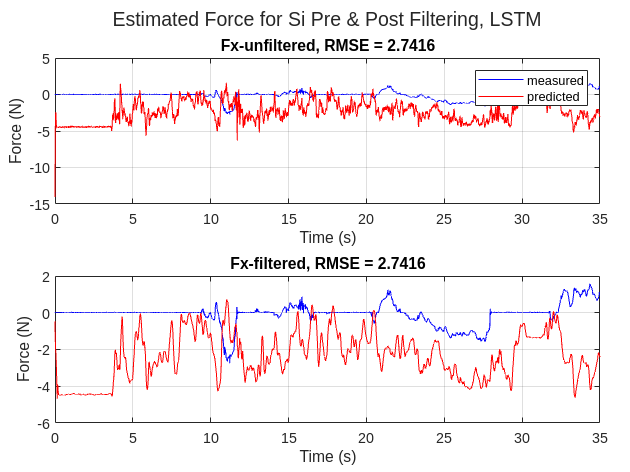


% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,4), 'b')
% hold on
% title(sprintf('Taux, RMSE = %.4f', loss_taux))
% plot(joint_data(1:length(fs_force)), fs_force(:,4), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,5), 'b')
% hold on
% title(sprintf('Tauy, RMSE = %.4f', loss_tauy))
% plot(joint_data(1:length(fs_force)), fs_force(:,5), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,6), 'b')
% hold on
% title(sprintf('Tauz, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(joint_data(1:length(fs_force)), fs_force(:,6), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% legend('measured', 'predicted')
% hold off








% 
% 
% 
% 
% nexttile
% plot(real_force(:,1), 'b')
% hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
% plot(fs_force(:,1), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,2), 'b')
% hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
% plot(fs_force(:,2), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,3), 'b')
% hold on
% title(sprintf('Fz, RMSE = %.4f', loss_z))
% plot(fs_force(:,3), 'r')
% hold off
% 




clf;

tcl = tiledlayout(2,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Estimated Force for Si Pre & Post Filtering, LSTM'))

loss_x_unfilt = mean(sqrt(mean( (fs_force_unfilt(:,1) - real_force(:,1)).^2 )));

nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx-unfiltered, RMSE = %.4f', loss_x_unfilt))
plot(joint_data(1:length(real_force)), fs_force_unfilt(:,1), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
legend('measured', 'predicted')
grid on
hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx-filtered, RMSE = %.4f', loss_x))
plot(joint_data(1:length(real_force)), fs_force_filt(:,1), 'r')

xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off






% 
% nexttile
% plot(real_force(:,4), 'b')
% hold on
% title(sprintf('taux, RMSE = %.4f', loss_taux))
% plot(fs_force(:,4), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,5), 'b')
% hold on
% title(sprintf('\tauy, RMSE = %.4f', loss_tauy))
% plot(-fs_force(:,5), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,6), 'b')
% hold on
% title(sprintf('\tau z, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(fs_force(:,6), 'r')
% legend('measured', 'predicted')
% hold off




% t = jacobian(1,:,:);


% jacobian = jacobian.numpy()
% force = torch.zeros((joints.shape[0], 6))
% for i in range(joints.shape[0]):
%     j = jacobian[i,:].reshape(6,6)
%     jacobian_inv_t = torch.from_numpy(np.linalg.inv(j).transpose())
%     force[i,:] = torch.matmul(jacobian_inv_t, joints[i,:])
% return force